##  **Practical Problems 6 – Matrices & Systems of Equations**

**1. **Use the **eye** function to create a 4 x 5 diagonal matrix called ***A*** with 7’s on the leading diagonal.

A = eye(4, 5);
for n = 1:4
    A(n, n) = 7;
end
A

A =      7     0     0     0     0
     0     7     0     0     0
     0     0     7     0     0
     0     0     0     7     0


2. Create a 3 x 3 elementary matrix called ***E*** that adds 3 of the 1st row to the 3rd row of a matrix. Test it with a random 3 x 3 matrix of integers.

E = randi(10, [3, 3])

E =      3     4     1
     7     8     7
     9     7     4


randomMat = randi(10, [3, 3])

randomMat =     10     5     4
     1     5     8
     5     8     5



E * randomMat

ans =     39    43    49
   113   131   127
   117   112   112


3. Augment the test matrix from question 2 with a 3 x 3 identity matrix then use Matlab’s **rref** function to find it’s reduced echelon form.

q3 = [E,eye(3,3)]

q3 =      3     4     1     1     0     0
     7     8     7     0     1     0
     9     7     4     0     0     1


rref(q3)

ans =     1.0000         0         0   -0.2576   -0.1364    0.3030
         0    1.0000         0    0.5303    0.0455   -0.2121
         0         0    1.0000   -0.3485    0.2273   -0.0606


4. Create the coefficient matrix for the following linear system, check that its determinant is not 0, then calculate the solution using the inverse matrix method (*hint:* you can find the inverse of a matrix with the **inv** function).

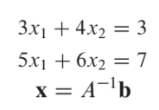

syms x1 x2
f = 3 * x1 + 4 * x2 - 3;
g = 5 * x1 + 6 * x2 - 7;
coeffMat = [equationsToMatrix(f); equationsToMatrix(g)];
if det(coeffMat) ~= 0
    b = [3; 7];
    inv(coeffMat) * b
end

$$ans = \left(\begin{array}{c} 5\\ -3 \end{array}\right)$$

5. Solve the system above but using Matlab’s left-division operator.

coeffMat\b

$$ans = \left(\begin{array}{c} 5\\ -3 \end{array}\right)$$

6. There are 3 reactors linked by pipes as shown below. The rate of transfer of chemicals through each pipe is equal to a flow rate (Q, with units of cubic meters per ­second) multiplied by the concentration of the reactor from which the flow originates (c, with units of milligrams per cubic meter). If the system is at a steady state, the transfer into each reactor will balance the transfer out. Develop mass-balance equations for the reactors and solve the three simultaneous linear algebraic equations for their concentrations.

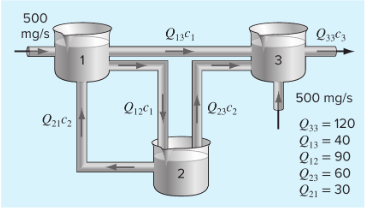

syms c1 c2 c3
cup1 = 500 + 30 * c2 - 130 * c1;
cup2 = 90 * c1 - 90 * c2;
cup3 = 500 + 60 * c2 + 40 * c1 - 120 * c3;
equationsToMatrix(cup1)

$$ans = \left(\begin{array}{cc} -130 & 30 \end{array}\right)$$

coMat = [equationsToMatrix(cup1), 0; equationsToMatrix(cup2), 0; equationsToMatrix(cup3);]

$$coMat = \left(\begin{array}{ccc} -130 & 30 & 0\\ 90 & -90 & 0\\ 40 & 60 & -120 \end{array}\right)$$

b = [500 ; 0 ; 500];

abs(double(coMat \ b))

ans =     5.0000
    5.0000
    8.3333


7. Use Matlab’s **fsolve** function to find the roots of the system. Since there are infinite solutions you do not need to find every root. Just locate and plot those given in the default window. Plotting is always a good idea to give you an idea of how many roots you are looking for and where to make the initial guesses. Use the **fimplicit** function to plot these implicit functions on the same graph. Define a function at the end of your script closed with keyword **end** that holds the system of equations. Advanced users can also use the ginput() function to pick starting initial guesses.

fsolve(exp(x*y)-(y^2)-cos(x + y))

Operator '*' is not supported for operands of type 'function_handle'.